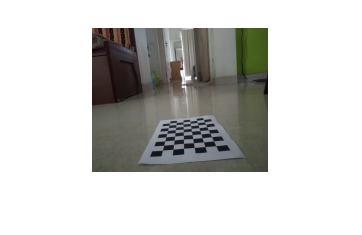

Ixx = imread('k1.png');  % read the image into the matrix
imshow(Ix);          % display the image

pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/deeplabv3plusResnet18CamVid.mat';
pretrainedFolder = fullfile(tempdir,'pretrainedNetwork');
pretrainedNetwork = fullfile(pretrainedFolder,'deeplabv3plusResnet18CamVid.mat'); 
if ~exist(pretrainedNetwork,'file')
    mkdir(pretrainedFolder);
    disp('Downloading pretrained network (58 MB)...');
    websave(pretrainedNetwork,pretrainedURL);
end

data = load(pretrainedNetwork); 
net = data.net;
Ix=imread('k1_large.png');
%Ix=imresize(Ix,[720 960]);
C = semanticseg(Ix, net);

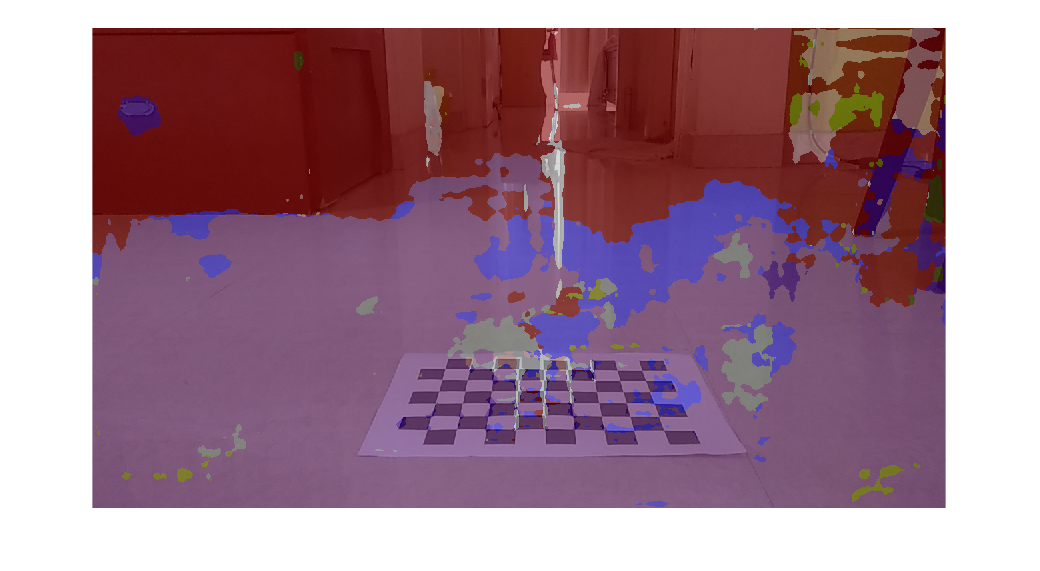

cmap = camvidColorMap;
B = labeloverlay(Ix,C,'Colormap',cmap,'Transparency',0.4);
imshow(B)

%pixelLabelColorbar(cmap, classes);

H=[0.0030 0.0037 -0.4335;
    0.0007 0.0097 -0.9011;
    0.0000 0.0000 -0.0023]

H =     0.0030    0.0037   -0.4335
    0.0007    0.0097   -0.9011
         0         0   -0.0023


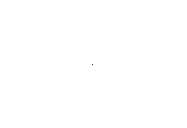

T = projective2d(H);
J = imwarp(Ixx,T);
imshow(J);

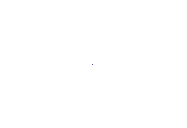

T = projective2d(H);
J = imwarp(B,T);
imshow(J);

imshow(J);